%% Setting up 

clear all; clc;

fn = 'RawOCT_A';
loadloc = './';
load(fullfile(loadloc,fn));

NumPoints=size(RawOCT_A,1);
NumAscans=size(RawOCT_A,2);
NumBscans=size(RawOCT_A,3);

folder_LUT = './';
fileID = fopen(fullfile(folder_LUT,'LUT_A.bin'),'r'); 
LUT_A = fread(fileID,'double'); fclose(fileID);


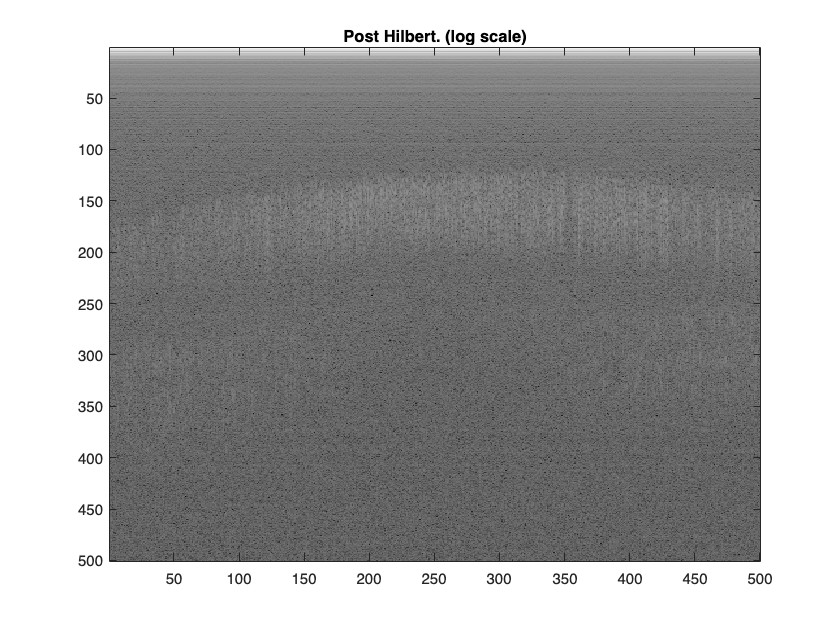

%%Hilbert

Ref_CplxRawOCT = hilbert(RawOCT_A(:,:,round(end/2)));

Ref_FFTData = fft(Ref_CplxRawOCT);
Ref_OCTimg = 20.*log10(abs(Ref_FFTData(1:500,:)));
imagesc(Ref_OCTimg); colormap("gray"); title('Post Hilbert. (log scale)');


%plot(1:2048,Ref_CplxRawOCT);

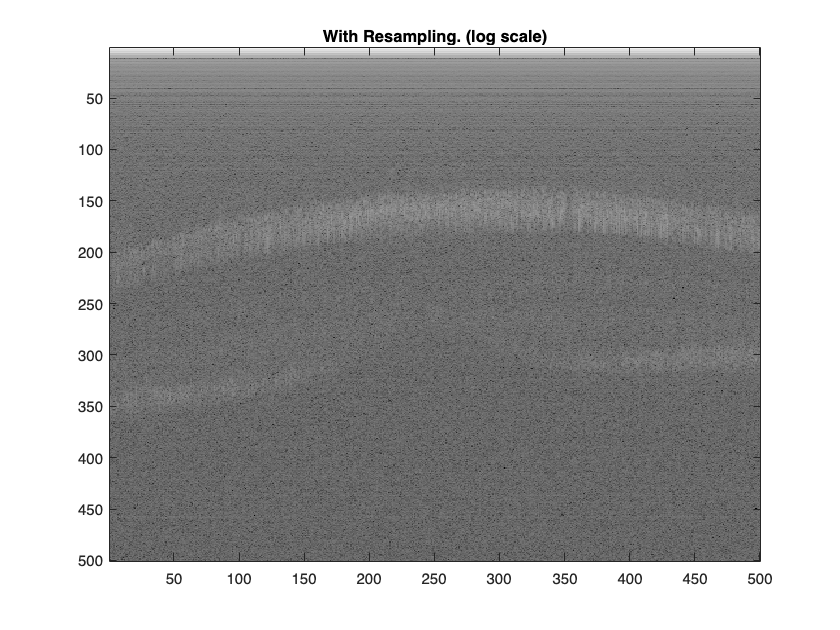

%% With Resampling

Ref_CplxRawOCT_Rescaled = reSampling_LUT(Ref_CplxRawOCT, LUT_A);

Ref_FFTData = fft(Ref_CplxRawOCT_Rescaled);
Ref_OCTimg = 20.*log10(abs(Ref_FFTData(1:500,:)));
imagesc(Ref_OCTimg); colormap("gray"); title('With Resampling. (log scale)');


%plot(1:2048,Ref_CplxRawOCT_Rescaled);

%Without Resampling
% 
% Ref_CplxRawOCT_Rescaled = Ref_CplxRawOCT;
% 
% Ref_FFTData = fft(Ref_CplxRawOCT_Rescaled);
% Ref_OCTimg = 20.*log10(abs(Ref_FFTData(1:500,:)));
% imagesc(Ref_OCTimg); colormap("gray"); title('Without Resampling. (log scale)');

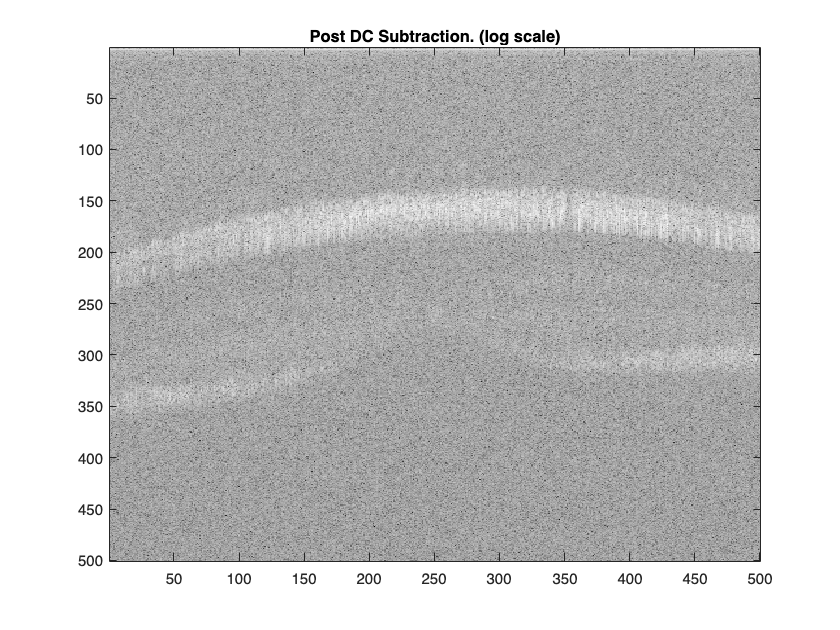

%% DC Subtraction

Ref_CplxRawOCT_DCSub = Ref_CplxRawOCT_Rescaled - (repmat(median(real(Ref_CplxRawOCT_Rescaled),2), [1,size(Ref_CplxRawOCT_Rescaled,2)])+1j.*repmat(median(imag(Ref_CplxRawOCT_Rescaled),2), [1,size(Ref_CplxRawOCT_Rescaled,2)]));

Ref_FFTData = fft(Ref_CplxRawOCT_DCSub);
Ref_OCTimg = 20.*log10(abs(Ref_FFTData(1:500,:)));
imagesc(Ref_OCTimg); colormap("gray"); title('Post DC Subtraction. (log scale)');

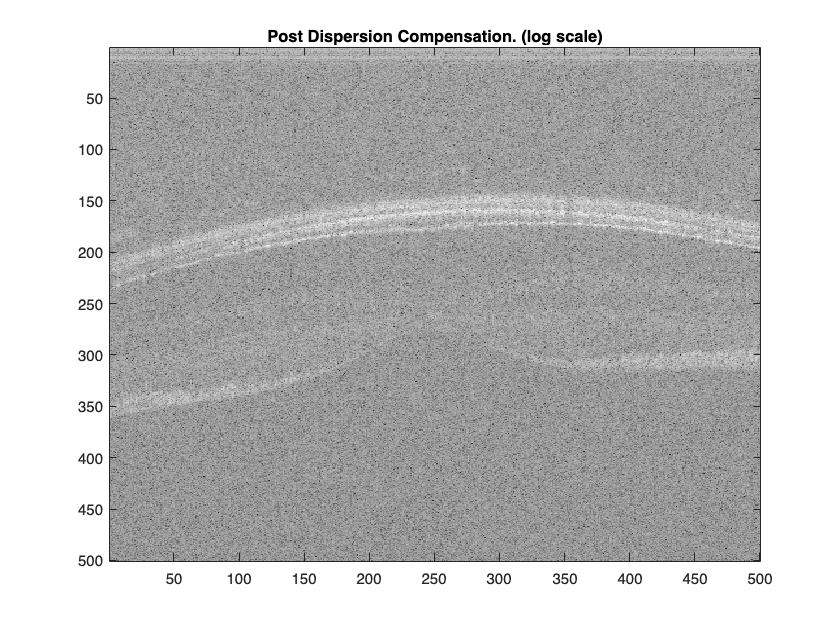

%% Dispersion Compensation

% Set dispersion estimation parameters %
dispMaxOrder = 4;
coeffRange = 20;
depthROI = [14, 590];

% Dispersion estimation %
[dispCoeffs, arrDispCoeff, arrCost] = setDispCoeff(Ref_CplxRawOCT_DCSub,depthROI,dispMaxOrder,coeffRange);

% Dispersion correction %
CplxRawData_DispCorr = compDisPhase(Ref_CplxRawOCT_DCSub,dispMaxOrder,dispCoeffs);


Ref_FFTData = fft(CplxRawData_DispCorr);
Ref_OCTimg = 20.*log10(abs(Ref_FFTData(1:500,:)));
imagesc(Ref_OCTimg); colormap("gray"); title('Post Dispersion Compensation. (log scale)');

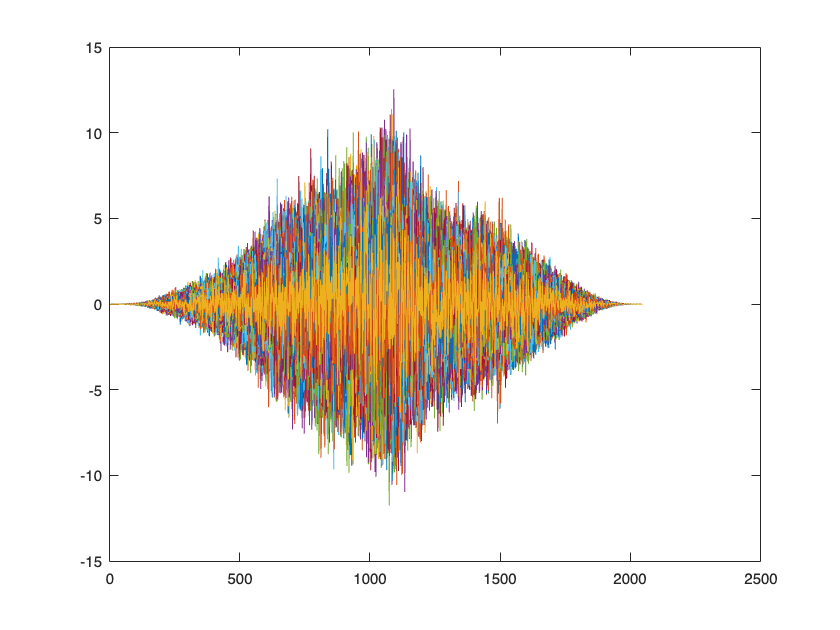

%% Windowing

CplxRawData_win = CplxRawData_DispCorr.*repmat(hann(size(CplxRawData_DispCorr,1)), [1 size(CplxRawData_DispCorr,2)]);

% Windowing Check
plot(1:2048,CplxRawData_win);

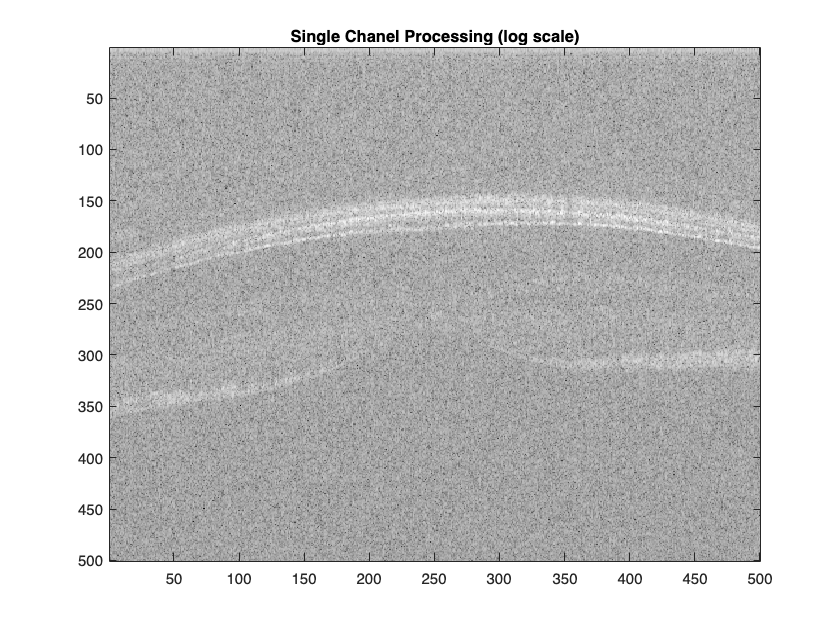

%% Final Image.
Ref_FFTData = fft(CplxRawData_win);
Ref_OCTimg = 20.*log10(abs(Ref_FFTData(1:500,:)));
imagesc(Ref_OCTimg); colormap("gray"); title('Single Chanel Processing (log scale)');

## Volume Processing

% load stuff
% load('cached/RawOCT_A_Processed.mat')
% load('cached/RawOCT_A_dispCoeffs-arrDispCoeff-arrCost.mat')

first_run = not(exist('dispCoeffs', 'var'));


% first run to generate the dispersion correction factors
if ~first_run
    disp("generating dispersion correction factors")
    % loadloc = './data';
    % fn = 'RawOCT_A';
    % load(fullfile(loadloc,fn));
    
    numPoints = size(RawOCT_A, 1);
    numAScans = size(RawOCT_A, 2);
    numBscans = size(RawOCT_A, 3);
    
    % folder_LUT = './LUT';
    % fileID = fopen(fullfile(folder_LUT,'LUT_A.bin'),'r');
    % LUT_A = fread(fileID,'double'); fclose(fileID);
    
    % dispersion
    dispMaxOrder = 4;
    coeffRange = 20;
    depthROI = [100 350];
    
    % 1.
    hilbert_fringe = hilbert(RawOCT_A(:,:,round(end/2)));

    % 2.
    rescaled_fringe = reSampling_LUT(hilbert_fringe, LUT_A);
    
    % 3.
    DCsub_fringe = rescaled_fringe - (repmat(median(real(rescaled_fringe),2), [1,size(rescaled_fringe,2)]) ...
        +1j.*repmat(median(imag(rescaled_fringe),2), [1,size(rescaled_fringe,2)]));
    
    % 4.
    [dispCoeffs, arrDispCoeff, arrCost] = setDispCoeff(DCsub_fringe, depthROI, dispMaxOrder, coeffRange);
    
    dispersion_comp_fringe = compDisPhase(DCsub_fringe, dispMaxOrder, dispCoeffs);
   
    % 5.
    hanwin_fringe = dispersion_comp_fringe.*repmat(hann(size(dispersion_comp_fringe, 1)), [1 size(dispersion_comp_fringe,2)]);

    first_run = false;
end

generating dispersion correction factors


%%
first_loop = exist('OCT','var'); % set to false if we have OCT matrix generated 
if ~first_loop
    % going along each frame
    disp("initial processing, no tilt corr")

    for FrameNum = 1:numBscans
        RawOCT = RawOCT_A(:,:,FrameNum);

        rescaled = reSampling_LUT(RawOCT, LUT_A);
        dc_sub = rescaled - (repmat(median(real(rescaled),2), [1,size(rescaled,2)]) ...
        +1j.*repmat(median(imag(rescaled),2), [1,size(rescaled,2)]));

        % no need to estimate, just apply
        dis_comp = compDisPhase(dc_sub, dispMaxOrder, dispCoeffs);

        han_win = dis_comp.*repmat(hann(size(dis_comp, 1)), [1 size(dis_comp,2)]);

        FFTData = fft(han_win);

        OCT(:,:,FrameNum) = flipud(FFTData(depthROI(1):depthROI(2),:));
    end
end

initial processing, no tilt corr



% % Save .mat file %
% save(fullfile(loadloc,['OCT']), 'OCT', '-v7.3');
% 
% % Save .tiff stack %
% for i = 1:size(OCT,3)
%     img = imadjust(mat2gray(20.*log10(abs(OCT(:,:,i)))));
%     imwrite(img, 'OCT.tiff', 'WriteMode', 'append', 'Compression','none');
% end
% 
% return

% % idk yet
usfac = 1;
numFrames = size(OCT, 3);
global_axial_motion = zeros([numFrames 1]);
OCT_mcorr = OCT;

for I = 1:numFrames
    %%% Every 'for' loop, reference frame will be the middle frame %%%
    [output, ~] = dftregistration(fft2(20.*log10(abs(OCT(:, :, round(numFrames./2))))),...
    fft2(20.*log10(abs(OCT(:, :, I)))), usfac);
    %%% Assign and save the shifting value for axial (yShift) %%%
    global_axial_motion(I) = round(output(3));
    OCT_mcorr(:, :, I) = circshift(OCT(:, :, I), [output(3), 0]);
end

numLines = size(OCT_mcorr, 2);
global_axial_tilt = zeros([numLines 1]);
OCT_tcorr = OCT_mcorr;
OCT_tcorr_fit = OCT_mcorr;

for I = 1:numLines
    %%% Every 'for' loop, reference frame will be the middle frame %%%
    [output, ~] = dftregistration(fft2(squeeze(OCT_mcorr(:, round(numLines./2), :))),...
    fft2(squeeze(OCT_mcorr(:, I, :))), usfac);
    %%% Assign and save the shifting value for lateral (xShift) and axial (yShift) %%%
    global_axial_tilt(I) = round(output(3));
    OCT_tcorr(:, I, :) = circshift(OCT_mcorr(:, I, :), [output(3), 0]);
end

x = [1:numLines]';
cx = polyfit(x,global_axial_tilt,2);
global_axial_tilt_fit = polyval(cx, x);


% Save .tiff stack %
for i = 1:size(OCT_tcorr,3)
    img = imadjust(mat2gray(20.*log10(abs(OCT_tcorr(:,:,i)))));
    imwrite(img, 'OCT_tcorr.tiff', 'WriteMode', 'append', 'Compression','none');
end

return